# Exchange Data with ROS 2 Publishers and Subscribers

The primary mechanism for ROS 2 nodes to exchange data is to send and receive *messages*. Messages are transmitted on a *topic* and each topic has a unique name in the ROS 2 network. If a node wants to share information, it must use a *publisher* to send data to a topic. A node that wants to receive that information must use a *subscriber* for that same topic. Besides its unique name, each topic also has a *message type*, which determines the type of messages that are allowed to be transmitted in the specific topic. 

This publisher-subscriber communication has the following characteristics:

- Topics are used for many-to-many communication. Multiple publishers can send messages to the same topic and multiple subscribers can receive them.

- Publisher and subscribers are decoupled through topics and can be created and destroyed in any order. A message can be published to a topic even if there are no active subscribers.

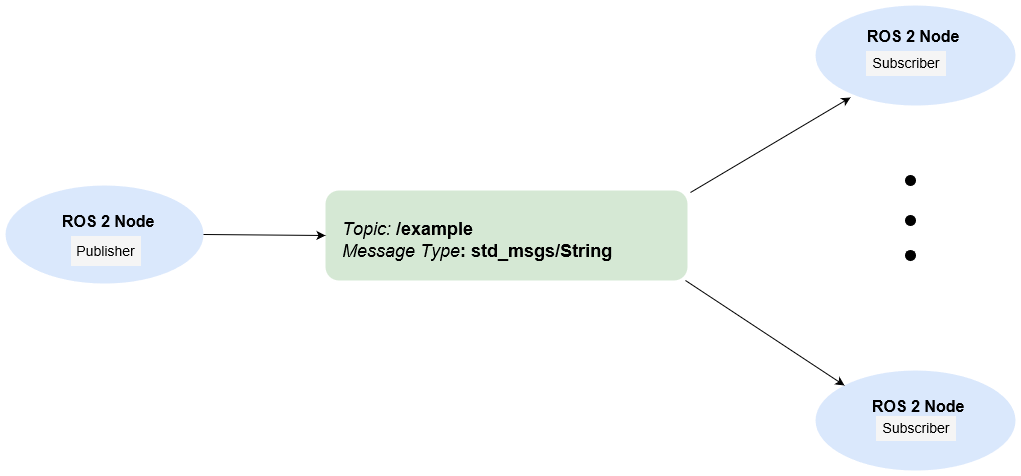

This example shows how to publish and subscribe to topics in a ROS 2 network. It also shows how to:

- Wait until a new message is received, or

- Use callbacks to process new messages in the background

Prerequisites: [Get Started with ROS 2](docid:ros_ug.mw_9aa75390-b989-436d-94b2-8125909cd238), [Connect to a ROS 2 Network](docid:ros_ug.mw_ef69ae07-7234-49b7-b384-86c479d401fd)

## Subscribe and Wait for Messages

Create a sample ROS 2 network with several publishers and subscribers.

exampleHelperROS2CreateSampleNetwork

Use `ros2 topic list` to see which topics are available.

ros2 topic list

Assume you want to subscribe to the `/scan` topic. Use `ros2subscriber` to subscribe to the `/scan` topic. Specify the name of the node with the subscriber. If the topic already exists in the ROS 2 network, `ros2subscriber` detects its message type automatically, so you do not need to specify it.

detectNode = ros2node("/detection");
pause(2)
laserSub = ros2subscriber(detectNode,"/scan");
pause(2)

Use `receive` to wait for a new message. Specify a timeout of 10 seconds. The output `scanData` contains the received message data.

scanData = receive(laserSub,10);

You can now remove the subscriber `laserSub` and the node associated to it.

clear laserSub
clear detectNode

## Subscribe Using Callback Functions

Instead of using `receive` to get data, you can specify a function to be called when a new message is received. This allows other MATLAB code to execute while the subscriber is waiting for new messages. Callbacks are essential if you want to use multiple subscribers.

Subscribe to the `/pose` topic, using the callback function `exampleHelperROS2PoseCallback`, which takes a received message as the input. One way of sharing data between your main workspace and the callback function is to use global variables. Define two global variables `pos` and `orient`.

controlNode = ros2node("/base_station");
poseSub = ros2subscriber(controlNode,"/pose",@exampleHelperROS2PoseCallback);
global pos
global orient

The global variables `pos` and `orient` are assigned in the  `exampleHelperROS2PoseCallback` function when new message data is received on the `/pose` topic.

Wait a moment for the network to publish another `/pose` message. Display the updated values.

pause(3)
disp(pos)
disp(orient)

If you type in `pos` and `orient` a few times in the command line you can see that the values are continuously updated.

Stop the pose subscriber by clearing the subscriber variable

clear poseSub
clear controlNode

*Note*: There are other ways to extract information from callback functions besides using globals. For example, you can pass a handle object as additional argument to the callback function. See the [Callback Definition](docid:creating_plots.bt_h1z8) documentation for more information about defining callback functions.

## Publish Messages

Create a publisher that sends ROS 2 string messages to the `/chatter` topic.

chatterPub = ros2publisher(node_1,"/chatter","std_msgs/String");

Create and populate a ROS 2 message to send to the `/chatter` topic.

chatterMsg = ros2message(chatterPub);
chatterMsg.data = 'hello world';

Use `ros2 topic list` to verify that the `/chatter` topic is available in the ROS 2 network.

ros2 topic list

Define a subscriber for the `/chatter` topic.  `exampleHelperROS2ChatterCallback` is called when a new message is received, and displays the string content in the message.

chatterSub = ros2subscriber(node_2,"/chatter",@exampleHelperROS2ChatterCallback)

Publish a message to the `/chatter` topic. Observe that the string is displayed by the subscriber callback.

send(chatterPub,chatterMsg)
pause(3)

The `exampleHelperROS2ChatterCallback` function was called when the subscriber received the string message.

## Disconnect From ROS 2 Network

Remove the sample nodes, publishers and subscribers from the ROS 2 network. Also clear the global variables `pos` and `orient`

clear global pos orient
clear 

## Next Steps

- [Work with Basic ROS 2 Messages](docid:ros_ug.mw_8a48f84f-f79b-4aa6-8163-a8ef53743751)

- [ROS 2 Custom Message Support](docid:ros_ug.mw_b9b240ff-c842-4139-9e7d-34e94cabc6fe)

*Copyright 2019 The MathWorks, Inc.*